# Example: Rosenbrock Banana Function

Author: Adolphus Lye (Email: adolphus.lye@liverpool.ac.uk)

## Problem: 

This case study is based on the literature by [Goodman and Weare (2010)](https://projecteuclid.org/download/pdf_1/euclid.camcos/1513731992).

In this example, the objective is to implement the Ensemble sampler and test its robustness in sampling from the highly-anisotropic [Rosenbrock Banana](https://academic.oup.com/comjnl/article/3/3/175/345501) function which takes the following form:


$$\pi \left(\mathit{\mathbf{x}}\right)\propto \mathrm{exp}\left\lbrack -\frac{100\cdot {\left(x_2 -x_1^2 \right)}^{2\;} +{\left(1-x_1 \right)}^2 }{20}\right\rbrack$$


An illustration of the Rosenbrock Banana function is provided below:

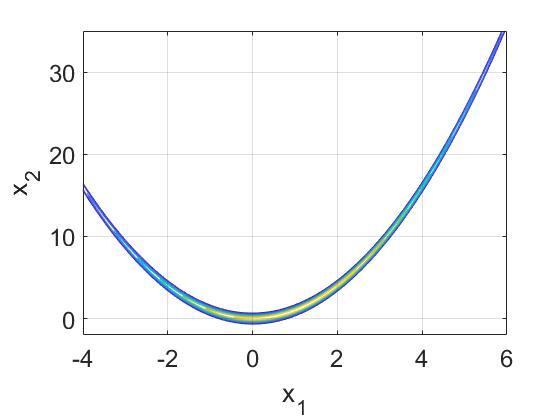

To demonstrate the robustness of the Ensemble sampler in sampling from such distribution, its sampling performance will be compared against that of the Metropolis-Hastings (MH) sampler. For this example, sampling will be done by each sampler using 4 chains, each chain generating 2000 samples.

## 1) Setting-up the problem:

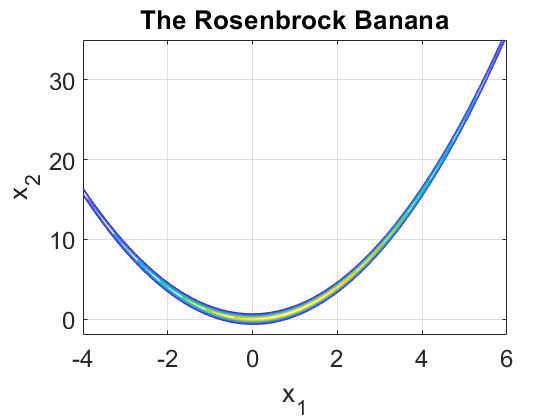

% Number of dimensions of the problem:
dim = 2; 

% Defining the log-target distribution:
logPfun = @(m) -(100*(m(:,2)-m(:,1).^2).^2 +(1-m(:,1)).^2)/20; 

% To generate an illustrative contour plot of the target distribution:
[X1,X2] = meshgrid(-4:.01:6,-5:.02:35);
Z = logPfun([X1(:) X2(:)]); 
Z = reshape(Z,size(X1));

figure();
hold on; box on; grid on;
contour(X1,X2,exp(Z))
colormap(parula)
title('The Rosenbrock Banana')
xlim([-4 6])
ylim([-2 35])
xlabel('x_1')
ylabel('x_2')
set(gca, 'fontsize', 18)

## 2) Sample using the Ensemble sampler:

### a) Defining the input parameters:

% Defining the total number of chains of the ensemble:
Nwalkers = 2*dim;  

% Defining the starting point of each chain:
start_emcmc = [unifrnd(-4, 6, Nwalkers, 1), unifrnd(-5, 35, Nwalkers, 1)];

% Defining the sample size per chain:
Nsamples_emcmc = 2000;

% Defining the burn-in length of each chain:
BurnIn_emcmc = 50;

% Defining the step-size of each chain:
step_size = 2; 
% Note: The step-size is chosen such that it gives the Ensemble sampler an
% overall acceptance rate that is close to 0.235.

### b) Initiate the Ensemble sampler:

tic;
EMCMC = EMCMCsampler(start_emcmc,logPfun,Nsamples_emcmc,'StepSize',step_size,'burnin',BurnIn_emcmc);

timeEMCMC = toc;
fprintf('Time elapsed is for the Ensemble sampler is: %f \n',timeEMCMC)

Time elapsed is for the Ensemble sampler is: 1.605391 


fprintf('The acceptance level of the Ensemble sampler is: %d. \n',EMCMC.acceptance)

The acceptance level of the Ensemble sampler is: 2.453661e-01. 


### c) To obtain the sample output:

% To extract the samples:
samps_emcmc = EMCMC.samples;

% Note that the output is in the form of a Nsamples x dim x Nwalker matrix.
% We need to flatten the chain and convert it to a N x dim matrix:
samples_emcmc = permute(samps_emcmc, [2 1 3]);
samples_emcmc = samples_emcmc(:,:)';

## 3) Sample using the MH sampler:

### a) Defining the input parameters:

% Defining the total number of chains of the MH sampler:
Nchains = Nwalkers;  

% Defining the tuning parameter of the MH sampler:  
tuning_mh = [0.1, 0; 0, 0.1]; 
% Note: The tuning parameter is chosen such that it gives the MH sampler an
% overall acceptance rate that is close to 0.235.

% Defining the proposal function of the MH sampler:
proppdf = @(CandidateSample,CurrentSample) mvnpdf(CandidateSample,CurrentSample,tuning_mh);
proprnd = @(CurrentSample) mvnrnd(CurrentSample,tuning_mh);

% Defining the starting point of each chain:
start_mh = [unifrnd(-4, 6, Nchains, 1), unifrnd(-5, 35, Nchains, 1)];

% Defining the sample size per chain:
Nsamples_mh = 2000;

% Defining the burn-in length of each chain:
BurnIn_mh = 50;

### b) Initiate the Metropolis-Hastings sampler:

tic; 
[samps_mh,accept] = mhsample(start_mh,Nsamples_mh,'logpdf',logPfun,'proppdf',proppdf...
    ,'proprnd',proprnd,'symmetric',1....
    ,'burnin',BurnIn_mh,'nchain',Nchains);
timeMH = toc;
fprintf('The acceptance level of the MH sampler is: %d. \n',accept)

The acceptance level of the MH sampler for Anisotropic case is 1.097561e-01. 
The acceptance level of the MH sampler for Anisotropic case is 5.004878e-01. 
The acceptance level of the MH sampler for Anisotropic case is 3.458537e-01. 
The acceptance level of the MH sampler for Anisotropic case is 1.468293e-01. 


fprintf('Time elapsed is for the MH sampler is: %f \n',timeMH)

Time elapsed is for the MH sampler for Anisotropic case: 0.640524 


### c) To obtain the sample output:

% Note that the output is in the form of a Nsamples x dim x Nchains matrix.
% We need to flatten the chain and convert it to a N x dim matrix:
samples_mh = permute(samps_mh, [2 1 3]);
samples_mh = samples_mh(:,:)';

## 4) Analysing the Results:

### a) Generating the scatterplot profiles:

#### i) Ensemble sampler: Scatterplot profile for $\pi \left(\mathit{\mathbf{x}}\right)$

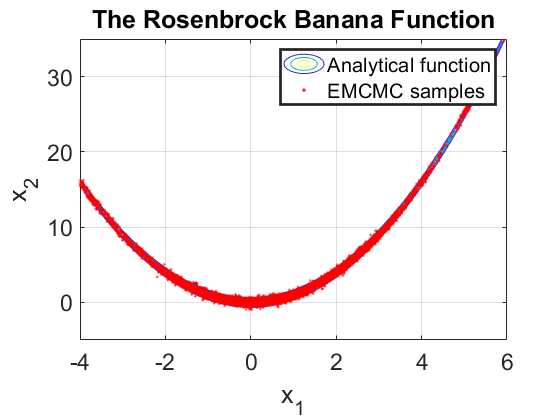

figure();
hold on; box on; grid on
contour(X1,X2,exp(Z))
colormap(parula)
title('The Rosenbrock Banana Function')
xlim([-4 6])
ylim([-5 35])
scatter(samples_emcmc(:,1),samples_emcmc(:,2), 15, 'r.')
xlabel('x_1')
ylabel('x_2')
legend('Analytical function','EMCMC samples', 'linewidth', 2)
set(gca, 'fontsize', 17)

#### ii) Metropolis-Hastings sampler: Scatterplot profile for $\pi \left(\mathit{\mathbf{x}}\right)$

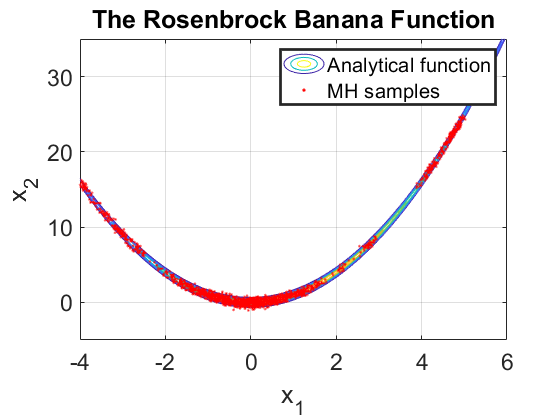

figure();
hold on; box on; grid on
contour(X1,X2,exp(Z))
colormap(parula)
title('The Rosenbrock Banana Function')
xlim([-4 6])
ylim([-5 35])
scatter(samples_mh(:,1),samples_mh(:,2), 15, 'r.')
xlabel('x_1')
ylabel('x_2')
legend('Analytical function','MH samples', 'linewidth', 2)
set(gca, 'fontsize', 17)

### b) Generating the Empirical CDFs:

#### i) Plot the Analytical Marginal CDFs for $x_1$and $x_2$:

% Defining the target distribution in real space:
fun = @(x1,x2) exp(-(100*(x2 - x1.^2).^2 +(1 - x1).^2)/20);

% Marginal PDF distribution of x1:
fun_x1 = @(x1) integral(@(x2) fun(x1,x2),-5,35);

% Marginal PDF distribution of x2:
fun_x2 = @(x2) integral(@(x1) fun(x1,x2),-4,6);

% To generate marginal CDFs for x1 and x2
fun_x1_out = zeros(1000,1); fun_x2_out = zeros(1000,1);
x1 = linspace(-4,6,1000); x2 = linspace(-5,35,1000);
for i = 1:1000
fun_x1_out(i) = fun_x1(x1(i)); 
fun_x2_out(i) = fun_x2(x2(i));
end

% Analytical marginal CDF for x1 (after normalization):
fun_x1_out = normalize(cumsum(fun_x1_out),'range',[0,1]);

% Analytical marginal CDF for x2 (after normalization):
fun_x2_out = normalize(cumsum(fun_x2_out),'range',[0,1]);

#### ii) Plot the ECDFs for $x_1$and $x_2$:

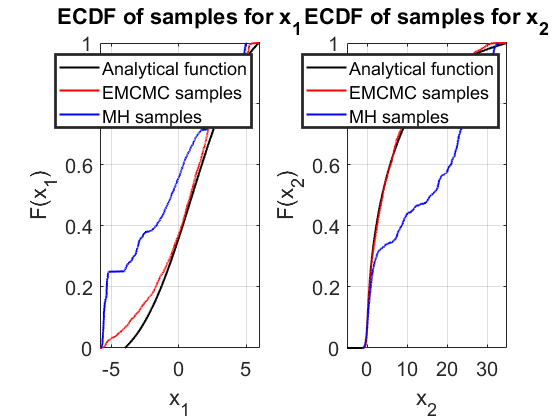

figure();
subplot(1,2,1)
hold on; box on; grid on;
plot(x1,fun_x1_out,'k','linewidth',1.5);
[f1a,x1a]=ecdf(samples_emcmc(:,1));
plot(x1a,f1a,'r','LineWidth',1.5)
[f1b,x1b]=ecdf(samples_mh(:,1));
plot(x1b,f1b,'b','LineWidth',1.5)
xlabel('x_1')
ylabel('F(x_1)')
legend('Analytical function','EMCMC samples', 'MH samples', 'linewidth',2);
title('ECDF of samples for x_1')
set(gca, 'Fontsize', 15)

subplot(1,2,2)
hold on
box on
plot(x2,fun_x2_out,'k','linewidth',1.5);
[f2a,x2a]=ecdf(samples_emcmc(:,2));
plot(x2a,f2a,'r','LineWidth',1.5)
[f2b,x2b]=ecdf(samples_mh(:,2));
plot(x2b,f2b,'b','LineWidth',1.5)
xlabel('x_2')
ylabel('F(x_2)')
legend('Analytical function','EMCMC samples', 'MH samples', 'linewidth',2);
title('ECDF of samples for x_2')
grid on
hold off
set(gca, 'Fontsize', 15)

## 5) Save the data:

% To save all the data from this file:
save Example_Rosenbrock.mat;


%%%%%%%%%%%%%%%%%%%%%%%%%%%% End of code %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
